%% MODELO TOE - ANIMACIÓN DE LA FUNCIÓN DE WIGNER EN EL ESPACIO DE FASES W(x,p)
% Generación de GIF de la evolución temporal del Oscilador 1
% Autor: Kilian Hernández Cabrera

clear; clc; close all;

%% 0. RUTAS Y ARCHIVO DE SALIDA (ESCRITORIO)
if ispc
    desktop_path = fullfile(getenv('USERPROFILE'), 'Desktop');
else
    desktop_path = fullfile(getenv('HOME'), 'Desktop');
end

gif_filename = fullfile(desktop_path, 'wigner_evolution.gif');
fprintf('El GIF se guardará en: %s\n', gif_filename);

El GIF se guardará en: C:\Users\Usuario\Desktop\wigner_evolution.gif


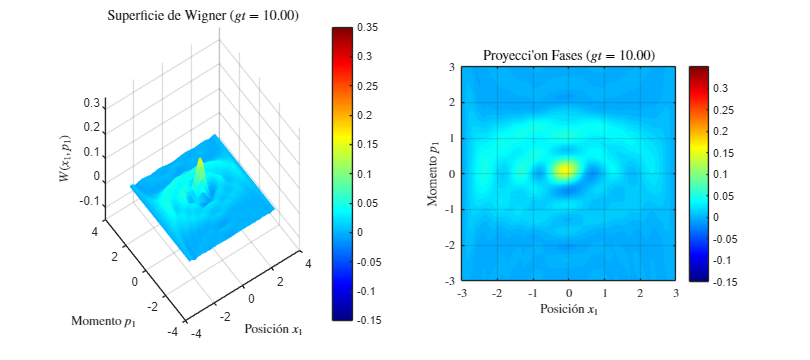


%% 1. PARÁMETROS DEL SISTEMA
hbar = 1; g = 1.0; lambda = 0.8; % Régimen de acoplamiento fuerte
w1 = 1.0; w2 = 1.0; w3 = 1.0;
n_max = 5; % Dimensión de Fock (0..5)

dim_q = 3; dim_osc = n_max + 1;
dim_single = dim_q * dim_osc;
dim_total = dim_single^3;

%% 2. OPERADORES BASE
X_q = [0 0 1; 1 0 0; 0 1 0];
a_osc = zeros(dim_osc);
for n = 1:(dim_osc-1), a_osc(n, n+1) = sqrt(n); end
adag_osc = a_osc'; N_osc = adag_osc * a_osc;

I_q = eye(dim_q); I_osc = eye(dim_osc); I_single = eye(dim_single);

%% 3. EXTENSIÓN AL ESPACIO TOTAL Y HAMILTONIANO
X1 = kron(kron(X_q, I_osc), kron(I_single, I_single));
a1 = kron(kron(I_q, a_osc), kron(I_single, I_single)); adag1 = a1';
N1 = kron(kron(I_q, N_osc), kron(I_single, I_single));

X2 = kron(kron(I_single, kron(X_q, I_osc)), I_single);
a2 = kron(kron(I_single, kron(I_q, a_osc)), I_single); adag2 = a2';
N2 = kron(kron(I_single, kron(I_q, N_osc)), I_single);

X3 = kron(I_single, kron(I_single, kron(X_q, I_osc)));
a3 = kron(I_single, kron(I_single, kron(I_q, a_osc))); adag3 = a3';
N3 = kron(I_single, kron(I_single, kron(I_q, N_osc)));

H0 = hbar*w1*(N1 + 0.5*eye(dim_total)) + ...
     hbar*w2*(N2 + 0.5*eye(dim_total)) + ...
     hbar*w3*(N3 + 0.5*eye(dim_total));
H_dir = (hbar * g / 2) * (X1*X2*X3 + X1'*X2'*X3');
H_osc_dir = hbar * lambda * (X1*adag1 + X1'*a1 + X2*adag2 + X2'*a2 + X3*adag3 + X3'*a3);

H_total = H0 + H_dir + H_osc_dir;

%% 4. ESTADO INICIAL |Psi_0>
v_x = [1;0;0]; v_y = [0;1;0]; v_z = [0;0;1];
v_0 = zeros(dim_osc, 1); v_0(1) = 1;

ket_xyz0 = kron(kron(kron(v_x,v_0), kron(v_y,v_0)), kron(v_z,v_0));
ket_yzx0 = kron(kron(kron(v_y,v_0), kron(v_z,v_0)), kron(v_x,v_0));
ket_zxy0 = kron(kron(kron(v_z,v_0), kron(v_x,v_0)), kron(v_y,v_0));

psi_0 = (1/sqrt(3)) * (ket_xyz0 + ket_yzx0 + ket_zxy0);

% Diagonalización previa para acelerar la evolución
[V, D] = eig(H_total);
diag_D = diag(D);
c_0 = V' * psi_0;

%% 5. PRECALCULOS DE LA BASE ESPACIAL Y GRILLA DE WIGNER
x = linspace(-3, 3, 60); % Malla optimizada para cálculo dinámico rápido
p = linspace(-3, 3, 60);
[X, P] = meshgrid(x, p);

psi_n = zeros(dim_osc, length(x));
for n = 0:(dim_osc-1)
    H_n = hermitePoly_local(n, x);
    psi_n(n+1, :) = (1/pi^(1/4)) * (1/sqrt(2^n * factorial(n))) .* H_n .* exp(-x.^2 / 2);
end

y = linspace(-4, 4, 61);
dy = y(2) - y(1);

%% 6. BUCLE DE EVOLUCIÓN TEMPORAL Y GENERACIÓN DE GIF
t_vec = linspace(0, 10.0, 100); % 40 frames desde t=0 hasta t=6.0

fig = figure('Color', [1 1 1], 'Position', [100 100 900 400]);

for it = 1:length(t_vec)
    t_curr = t_vec(it);
    
    % Evolución temporal
    psi_t = V * (c_0 .* exp(-1i * diag_D * t_curr / hbar));
    
    % Traza parcial sobre el Oscilador 1
    Psi_tensor = reshape(psi_t, [dim_q, dim_osc, dim_q, dim_osc, dim_q, dim_osc]);
    Psi_perm = permute(Psi_tensor, [2, 1, 3, 4, 5, 6]);
    Psi_mat = reshape(Psi_perm, [dim_osc, dim_q^3 * dim_osc^2]);
    rho_osc1 = Psi_mat * (Psi_mat');
    
    % Cálculo de Wigner
    W = zeros(size(X));
    for ix = 1:length(x)
        for ip = 1:length(p)
            x_val = X(ip, ix);
            p_val = P(ip, ix);
            integrand = 0;
            
            for n = 0:(dim_osc-1)
                for m = 0:(dim_osc-1)
                    if abs(rho_osc1(n+1, m+1)) > 1e-6
                        psi_m_plus = interp1(x, psi_n(m+1,:), x_val + y/2, 'linear', 0);
                        psi_n_minus = interp1(x, psi_n(n+1,:), x_val - y/2, 'linear', 0);
                        term = rho_osc1(n+1, m+1) * psi_m_plus .* psi_n_minus .* exp(2i * p_val * y);
                        integrand = integrand + sum(term) * dy;
                    end
                end
            end
            W(ip, ix) = real(integrand) / (2*pi);
        end
    end
    
    % Renderizado de la figura
    clf;
    
    % Panel 1: Superficie 3D
    subplot(1,2,1);
    surf(X, P, W, 'EdgeColor', 'none');
    colormap(jet); colorbar; view([-35 45]);
    caxis([-0.15, 0.35]); zlim([-0.15 0.35]);
    xlabel('Posici\''on $x_1$', 'Interpreter', 'latex', 'FontSize', 11);
    ylabel('Momento $p_1$', 'Interpreter', 'latex', 'FontSize', 11);
    zlabel('$W(x_1, p_1)$', 'Interpreter', 'latex', 'FontSize', 11);
    title(sprintf('Superficie de Wigner ($g t = %.2f$)', t_curr), 'Interpreter', 'latex', 'FontSize', 12);
    
    % Panel 2: Mapa de Contornos 2D
    subplot(1,2,2);
    contourf(X, P, W, 30, 'LineColor', 'none');
    colormap(jet); colorbar; axis square;
    caxis([-0.15, 0.35]);
    xlabel('Posici\''on $x_1$', 'Interpreter', 'latex', 'FontSize', 11);
    ylabel('Momento $p_1$', 'Interpreter', 'latex', 'FontSize', 11);
    title(sprintf('Proyecci\''on Fases ($g t = %.2f$)', t_curr), 'Interpreter', 'latex', 'FontSize', 12);
    grid on; set(gca, 'TickLabelInterpreter', 'latex');
    
    drawnow;
    
    % Captura de fotograma para el GIF
    frame = getframe(fig);
    im = frame2im(frame);
    [imind, cm] = rgb2ind(im, 256);
    
    if it == 1
        imwrite(imind, cm, gif_filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.1);
    else
        imwrite(imind, cm, gif_filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.1);
    end
end


fprintf('GIF guardado con éxito en: %s\n', gif_filename);

GIF guardado con éxito en: C:\Users\Usuario\Desktop\wigner_evolution.gif



%% FUNCIÓN AUXILIAR POLINOMIOS DE HERMITE
function H = hermitePoly_local(n, x)
    if n == 0
        H = ones(size(x));
    elseif n == 1
        H = 2 * x;
    else
        H_prev2 = ones(size(x));
        H_prev1 = 2 * x;
        for k = 2:n
            H = 2 * x .* H_prev1 - 2 * (k - 1) * H_prev2;
            H_prev2 = H_prev1;
            H_prev1 = H;
        end
    end
end